# 1.3 数字系统的优点：精度、灵活性、可靠性（可重复）、时分复用

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。 四幅图对应教材 1.3 的四条优点；滤波器公式只在代码里出现，课堂不讲。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');   % 由 build_mlx 设置：Live Script 里每格单独一张图，便于阅读；普通运行时拼成一张图存 PNG
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end   % 图例：Live 模式放图下方不压数据；拼图模式自动避让
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end
fs = 100; n = 0:199; t = n/fs;
x = sin(2*pi*2*t) + 0.5*sin(2*pi*15*t);          % 与 1.2 相同的信号：2 Hz + 15 Hz
fgrid = linspace(0, fs/2, 501);
dtft = @(h, f) abs(exp(-1i*2*pi*f(:)/fs*(0:numel(h)-1)) * h(:)).';   % |H(f)|，直接按定义求和

## 演示1：精度——系数用多少位表示

21 点低通（截止 6 Hz，窗函数法；第 7 章会讲）。系数分别用 16 位和 4 位表示。

L = 21; k = 0:L-1; fc = 6;
hd = 2*fc/fs * sinc_unscaled(2*pi*fc/fs*(k - (L-1)/2));
w = 0.5 - 0.5*cos(2*pi*k/(L-1));
h = hd .* w; h = h / sum(h);
qcoef = @(v, bits) round(v * 2^(bits-1)) / 2^(bits-1);          % 定点：bits 位，±1 满量程
h16 = qcoef(h, 16); h4 = qcoef(h, 4);
H = dtft(h, fgrid); H16 = dtft(h16, fgrid); H4 = dtft(h4, fgrid);
db = @(v) 20*log10(max(v, 1e-6));

## 演示2：灵活性——同一套“硬件”，换一组系数就是另一个系统

hlp = h;                                          % 低通：留下 2 Hz
hhp = -h; hhp((L+1)/2) = hhp((L+1)/2) + 1;        % 高通：δ − 低通，留下 15 Hz
ylp = filter(hlp, 1, x); yhp = filter(hhp, 1, x); % 同一条语句 filter(b,1,x)，只换 b

## 演示3：可靠性——数字系统每次结果一样；模拟元件有漂移

y1 = filter(hlp, 1, x); y2 = filter(hlp, 1, x);   % 跑两次
repeatDiff = max(abs(y1 - y2));                   % 应为 0（不是“很小”，是精确为 0）
rng(20260918); runs = 100; fcRC = 6;
yAnalog = zeros(runs, numel(x));
for r = 1:runs
    fcr = fcRC * (1 + 0.05*(2*rand-1));           % 模拟 RC 元件 ±5% 漂移
    a = exp(-2*pi*fcr/fs);                        % 一阶 RC 低通的差分方程近似
    yAnalog(r, :) = filter(1-a, [1 -a], x);
end
analogSpread = max(max(yAnalog) - min(yAnalog));

## 演示4：时分复用——一套处理设备轮流处理 4 路信号

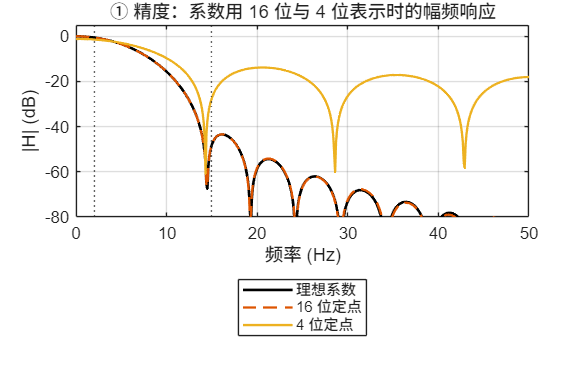

ch = [sin(2*pi*2*t); 0.8*sin(2*pi*3*t); 0.6*sin(2*pi*4*t + 1); 0.5*sin(2*pi*1*t)] + 0.5*sin(2*pi*15*t);
C = size(ch, 1);
stream = reshape(ch, 1, []);                      % 按时刻交织：ch1(0) ch2(0) ch3(0) ch4(0) ch1(1) ...
outStream = zeros(size(stream)); state = zeros(C, L-1);   % 一套乘加器 + 每路各自的状态
for i = 1:numel(stream)
    c = mod(i-1, C) + 1;
    [outStream(i), state(c, :)] = filter(hlp, 1, stream(i), state(c, :));
end
outCh = reshape(outStream, C, []);
sepCh = filter(hlp, 1, ch, [], 2);                % 各路单独处理作为对照
tdmDiff = max(abs(outCh(:) - sepCh(:)));          % 浮点舍入量级（1e-16）

if ~LIVE, f1 = figure('Name','02 数字系统的优点','Color','w','Position',[80 50 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(fgrid, db(H), 'k', 'LineWidth', 1.6); hold on;
plot(fgrid, db(H16), '--', 'LineWidth', 1.4); plot(fgrid, db(H4), 'LineWidth', 1.4); grid on; ylim([-80 5]);
xline(2, ':'); xline(15, ':');
title('① 精度：系数用 16 位与 4 位表示时的幅频响应'); xlabel('频率 (Hz)'); ylabel('|H| (dB)');
legend('理想系数','16 位定点','4 位定点');

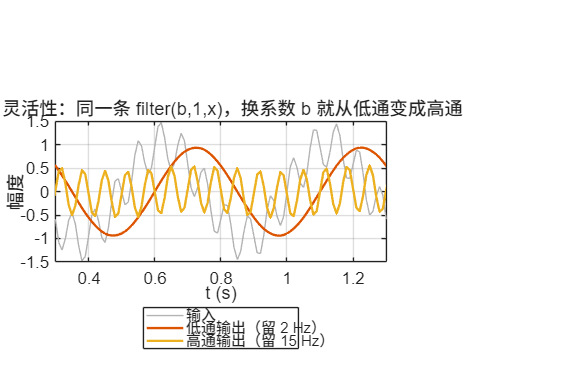

newpanel(); plot(t, x, 'Color', [0.7 0.7 0.7]); hold on;
plot(t, ylp, 'LineWidth', 1.4); plot(t, yhp, 'LineWidth', 1.4); grid on; xlim([0.3 1.3]);
title('② 灵活性：同一条 filter(b,1,x)，换系数 b 就从低通变成高通'); xlabel('t (s)'); ylabel('幅度');
legend('输入','低通输出（留 2 Hz）','高通输出（留 15 Hz）');

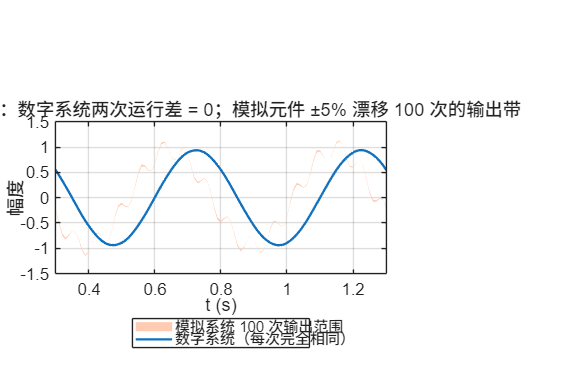

newpanel(); fill([t fliplr(t)], [max(yAnalog) fliplr(min(yAnalog))], [1 0.8 0.7], 'EdgeColor', 'none'); hold on;
plot(t, y1, 'LineWidth', 1.4); grid on; xlim([0.3 1.3]);
title(sprintf('③ 可靠性：数字系统两次运行差 = %g；模拟元件 ±5%% 漂移 100 次的输出带', repeatDiff));
xlabel('t (s)'); ylabel('幅度'); legend('模拟系统 100 次输出范围','数字系统（每次完全相同）');

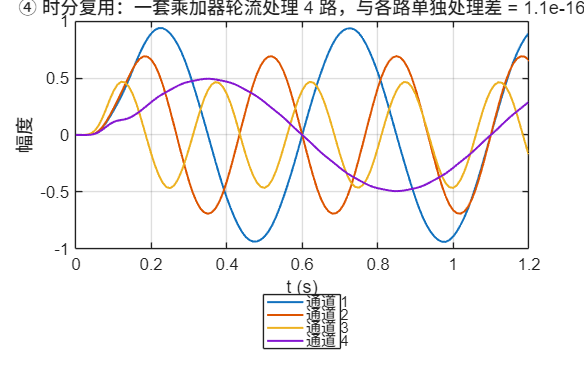

newpanel(); plot(t, outCh', 'LineWidth', 1.2); grid on; xlim([0 1.2]);
title(sprintf('④ 时分复用：一套乘加器轮流处理 %d 路，与各路单独处理差 = %.1e', C, tdmDiff));
xlabel('t (s)'); ylabel('幅度'); legend('通道 1','通道 2','通道 3','通道 4');

if ~LIVE, sgtitle('教材 1.3 的四条优点，各用一个小实验看到'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '02-digital-advantages.png'), 'Resolution', 150); end

## 教师核验

coefErr16 = max(abs(h - h16)); coefErr4 = max(abs(h - h4));
assert(coefErr16 <= 2^-16 + 1e-15 && coefErr4 <= 2^-4 + 1e-15, '系数量化误差超界');
assert(dtft(hlp, 2) > 0.9 && dtft(hlp, 15) < 0.05, '低通在 2 Hz 应接近 1、在 15 Hz 应接近 0');
assert(dtft(hhp, 2) < 0.1 && abs(dtft(hhp, 15) - 1) < 0.05, '高通在 15 Hz 应接近 1、在 2 Hz 应接近 0');
assert(repeatDiff == 0, '数字系统两次运行不一致');
assert(analogSpread > 0.01, '模拟漂移带过窄');
assert(tdmDiff < 1e-12, '时分复用结果与单独处理不一致');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'fs', fs, 'lowpass_taps', L, 'cutoff_hz', fc, 'coef_err_max_16bit', coefErr16, 'coef_err_max_4bit', coefErr4, ...
    'stopband_worst_db_16bit', max(db(H16(fgrid >= 12))), 'stopband_worst_db_4bit', max(db(H4(fgrid >= 12))), ...
    'stopband_worst_db_ideal', max(db(H(fgrid >= 12))), ...
    'lowpass_gain_2Hz', dtft(hlp, 2), 'lowpass_gain_15Hz', dtft(hlp, 15), 'highpass_gain_2Hz', dtft(hhp, 2), 'highpass_gain_15Hz', dtft(hhp, 15), ...
    'repeat_run_max_diff', repeatDiff, 'analog_drift_runs', runs, 'analog_output_spread_max', analogSpread, ...
    'tdm_channels', C, 'tdm_vs_separate_max_diff', tdmDiff, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-advantages.json'), 'w', 'n', 'UTF-8');
assert(fid >= 0, '无法创建核验记录');
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics);

              matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                      run_at: '2026-09-18 18:40:16'
                          fs: 100
                lowpass_taps: 21
                   cutoff_hz: 6
          coef_err_max_16bit: 1.1945e-05
           coef_err_max_4bit: 0.0577
     stopband_worst_db_16bit: -25.1520
      stopband_worst_db_4bit: -13.8121
     stopband_worst_db_ideal: -25.1391
            lowpass_gain_2Hz: 0.9398
           lowpass_gain_15Hz: 0.0040
           highpass_gain_2Hz: 0.0602
          highpass_gain_15Hz: 1.0040
         repeat_run_max_diff: 0
           analog_drift_runs: 100
    analog_output_spread_max: 0.0458
                tdm_channels: 4
    tdm_vs_separate_max_diff: 1.1102e-16
           all_checks_passed: 1



fprintf('\n课堂图已保存到：%s\n', outdir);


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function y = sinc_unscaled(z)
y = ones(size(z)); nz = (z ~= 0); y(nz) = sin(z(nz))./z(nz);
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList)
    axesList(a).Toolbar.Visible = 'off';
end
drawnow;
end